# Chap 7 Video understanding

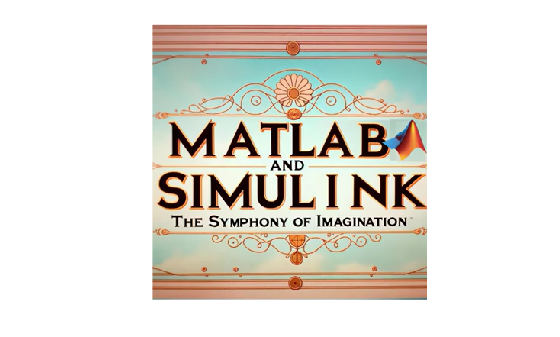

if ~exist("video_img\","dir")
    mkdir("video_img")
end
videoPath = "MATLAB and Simulink - The Symphony of Imagination.mp4";
v = VideoReader(videoPath);
imageFiles = strings(0);
frameIdx = 1;  
while hasFrame(v)                   
    frame = readFrame(v);            
    if mod(frameIdx, 60) == 1
        % Construct filename and save frame as JPEG
        filename = fullfile("video_img", sprintf("frame_%04d.jpg", frameIdx));
        imwrite(frame, filename);   
        imageFiles(end+1) = filename;
    end
    frameIdx = frameIdx + 1;
end

imshow(frame) % show the last frame

prompt = "These are frames of a movie trailer. Create a short voiceover script in the style of Wes Anderson. Only include the narration.";
response = chatVision(prompt, imageFiles,60) % Add timeOut to 60

response =     "**[Voiceover Script]**
     
     In a world where equations dance and dreams intertwine,  
     A young visionary named Max embarks on an extraordinary adventure.  
     
     Amidst charming chaos and whimsical whimsy,  
     He discovers that equations come to life,  
     Transforming the mundane into the marvelous —  
     A symphony of imagination unfolds.  
     
     Guided by the eccentric Prof. Anderson,  
     Together, they navigate a vibrant tapestry of numbers,  
     Where even the smallest details spark brilliance.  
     
     Join us as we explore this meticulously crafted universe,  
     Painted in pastel hues and peculiar patterns,  
     Where innovation meets artistry,  
     In a delightful collision of heart and mind.
     
     Prepare for an unforgettable journey,  
     In a new film by the inimitable Wes Anderson —  
     "MATLAB & Simulink: The Symphony of Imagination.""
